# 'volume' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### *Povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Load data

load mri;
data = squeeze(D);
data = data(:,:,1:27);

#### Normilize data

dmax = max(data(:));
dmin = min(data(:));
drange = dmax-dmin;
data = data / drange;


#### Map colors to data

num_colors = 256;
min_step = 0.0000;
max_step = 0.0055;
scale = (min_step: (max_step-min_step) / (num_colors-1): max_step);

%
% Select color map
%
%color_map_type = hot(num_colors);
%color_map_type = winter(num_colors);
%color_map_type = hsv(num_colors);
color_map_type = jet(num_colors);
%color_map_type = bone(num_colors);
%color_map_type = parula(num_colors);
%color_map_type = turbo(num_colors);
%color_map_type = spring(num_colors);

%
% Custom color map
%
% color_map = [0.00   0 0 0;
%              0.0001 0 0 1;
%              0.003  1 0 0;
%              0.005  0 0 1;
%              0.15   1 0 0;
%              0.20   0 0 1;
%              0.20   1 0 0;
%              0.30   0 1 0;
%              0.90   1 0 0;
%              1.00   1 0 0];

color_map = [scale' color_map_type];

#### Scene

pl.scene_begin('scene_file', 'volume.pov', 'image_file', 'volume.png');
    pl.global_settings("assumed_gamma 1");

    % Camere
    pl.camera('angle', 35, 'location', [8.5 8.5 3.4], 'look_at', [0 0 -0.2]);

    % Light
    pl.light('location', [5 5 3], 'color', [0.8 0.8 0.8]);

    % Prepare volume data for rendering
    pl.volume('data', data, 'density_file', 'test_vol', 'color_map', color_map, 'scale', [4 4 2]);
    
pl.scene_end();

#### Render and display

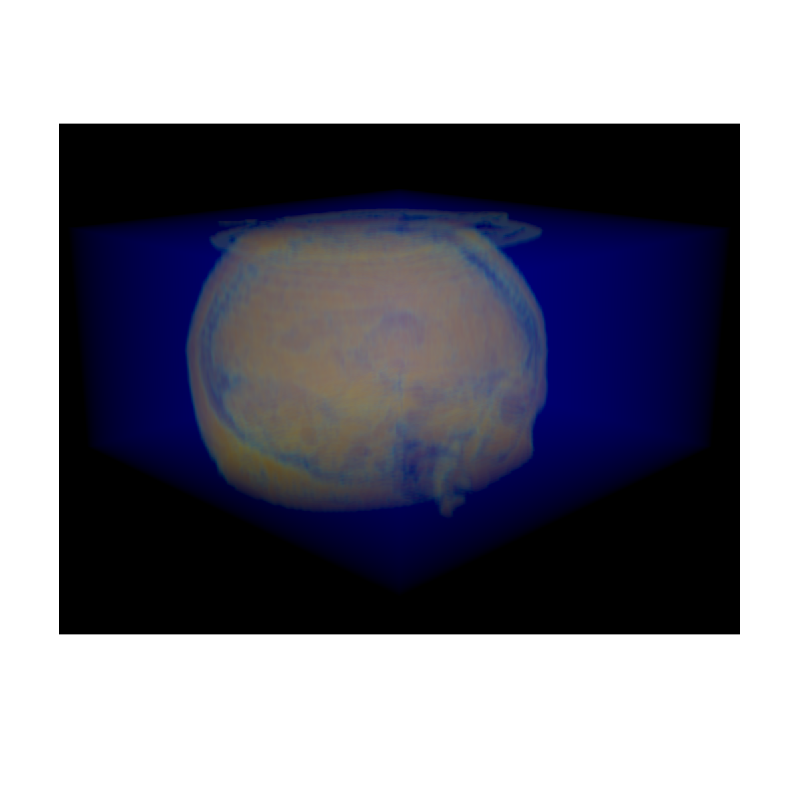

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 15.338462 seconds.
